% ODE1 - driver
    % ODE specifics
x0 = 1;
lambda = -0.2;
    % Solver specifics
N = 1000;
t0 = 0;
tN = 100;

[T, X] = ExplicitEulerFixedStepSize(@ODE1,t0,tN, N, x0, lambda);

T =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


X =     1.0000
    0.9800
    0.9604
    0.9412
    0.9224
    0.9039
    0.8858
    0.8681
    0.8508
    0.8337


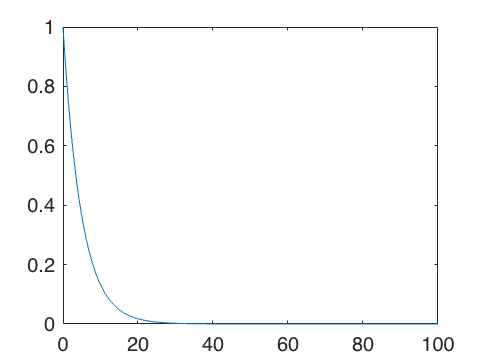

plot(T,X)

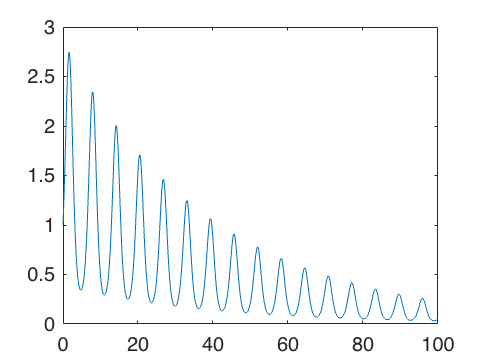

% ODE2
    % ODE specifics
x0 = 1;
c = 1;
    % Solver specifics
N = 1000;
t0 = 0;
tN = 100;

[T, X] = ExplicitEulerFixedStepSize(@ODE2,t0,tN, N, x0, c);
plot(T,X)

## Functions

function [T,X] = ExplicitEulerFixedStepSize(fun,t0,tN,N,x0,varargin)
% Compute step size and allocate memory
dt = (tN-t0)/N;
nx = size(x0,1);
X = zeros(nx,N+1);
T = zeros(1,N+1);

% Eulers Explicit Method
T(:,1) = t0;
X(:,1) = x0;
for k=1:N
    f = feval(fun,T(k),X(:,k),varargin{:});
    T(:,k+1) = T(:,k) + dt;
    X(:,k+1) = X(:,k) + f*dt;
end

% Form a nice table for the result
T=T';
X=X';
end

% ODE examples
function xdot = ODE1(t,x,lambda)
    xdot = zeros(1,1);
    xdot(1) = lambda * x(1);
end

function xdot = ODE2(t,x,c)
    xdot = zeros(1,1);
    xdot(1) = c*cos(t)*x(1);
end